# EFMouse: 1 x 1 with craniotomy montage

EFMouse is a Matlab tool for electric field modelling in the mouse brain.

This notebook reproduces results for the 1 x 1 with craniotomy montage in: 

Sanchez-Romero R, Akyuz S, Krekelberg B (2025) EFMouse: A toolbox to model stimulation-induced electric fields in the mouse brain. PLoS Comput Biol 21(9): e1013471. https://doi.org/10.1371/journal.pcbi.1013471

The notebook is also an introductory tutorial to simulate other montages.

Developed by Ruben Sanchez-Romero, Bart Krekelberg and Sibel Akyuz

Rutgers-Newark, Center for Molecular and Behavioral Neuroscience (CMBN)

For support open an issue in https://github.com/klabhub/EFMouse/issues

## Introduction

EFMouse combines several elements from previous work: 

- Anatomical data from the Digimouse project.

- A refined finite element mesh of the Digimouse by Alekseichuk et al., (2019), *Neuroimage*. 

- Matlab code and inspiration from the ROAST toolbox.

- The GetDP finite element method (FEM) solver (v 3.5.0).

- The Allen mouse brain atlas.

Key new functionality includes: 

- Positioning electrodes in arbitrary locations in and on the mouse body.

- Modeling craniotomies in the mouse skull.

- Analyzing the electric field in user-defined regions of interest

- Analyzing the electric field in brain regions defined in the Allen mouse atlas.

- A measure of relative focality of the electric field.

- A measure of direction homogeneity of the electric field.

For details see Sanchez-Romero et al., (2025) and *EFMouse.m* Matlab code.

## Typical workflow

The typical workflow to generate a model consists of several stages

- Stage.INIT           : Initialize. 

- Stage.MESH       : Define elecrodes and (optionally) a craniotomy.

- Stage.EXPORT   : Export files for the FEM solver GetDP.

- Stage.GETDP     : Run the FEM solver.

- Stage.ATLAS      : Map the results to the Allen mouse atlas.

### Stage INIT: Initialize

We start by setting up the basic parameters of the `EFMouse` object:

o = EFMouse; % Create a default empty object of the class EFMouse
o.ID = '1x1_craniotomy';  % A name/tag for this simulation.
o.dir = '/Users/rubensanchez/desktop/efmouse_sim/1x1_craniotomy'; % Results and the object (1x1_craniotomy.mat) will be saved here.
o.log  = true;  % Create a log file.

Note: The log file is created but doesn't update when running a simulation from a notebook (like here). It will properly update when running EFMouse directly from the Matlab command line.

`initialize()` creates the folder to store the results. With `overwrite=true`, anything in this folder will be deleted.

o.initialize(overwrite=true); 

The initialized `EFMouse` object contains the default mouse mesh (without stimulation electrodes). Let's visualize the brain tissue. You can select different tissues to visualize.

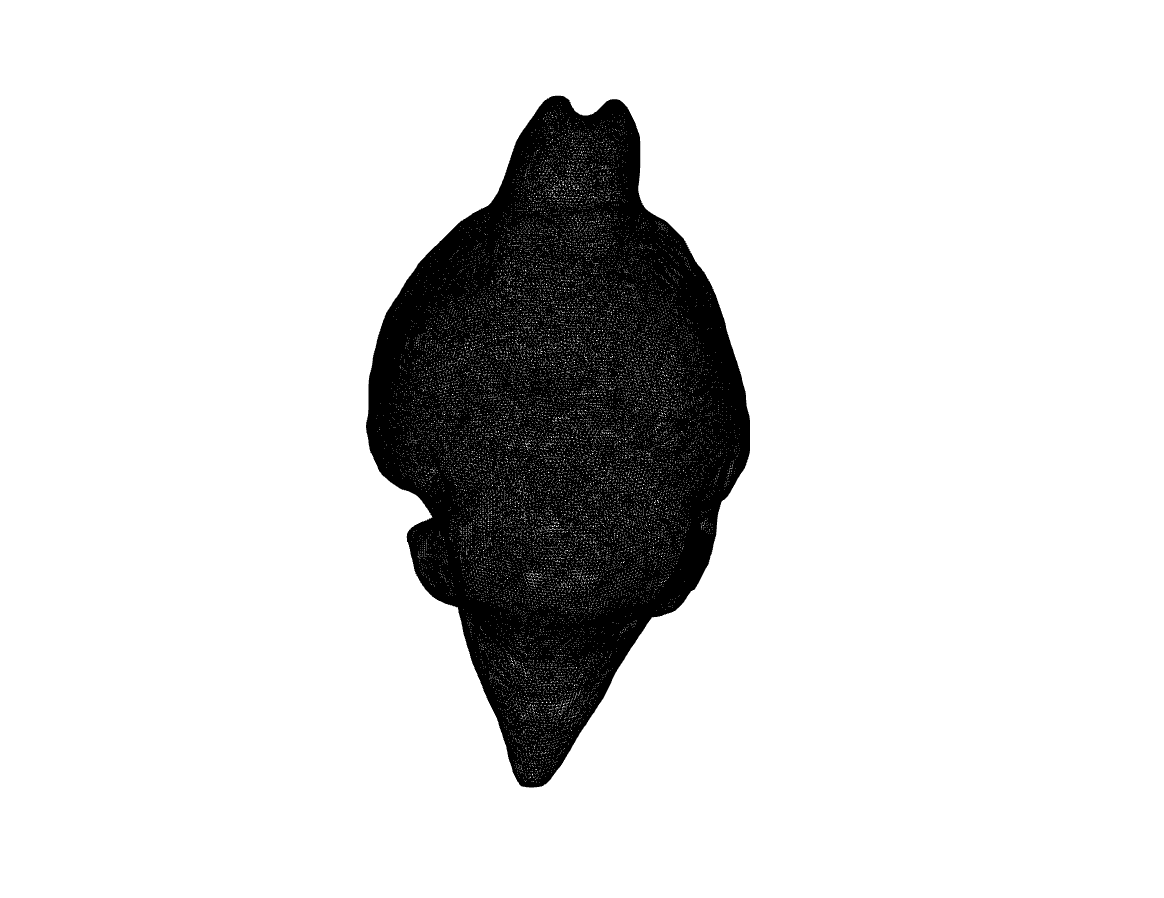

plotMesh(o,tissue='gray')

The mesh is pretty dense, so it may look like a black blob. The olfactory bulbs are visible on the top. In a regular figure window, you can use the Matlab figure tools to rotate or zoom. (You can also adapt the `plotMesh()` function in *EFMouse.m* to modifiy the figure directly.)

### Stage MESH: Create electrodes and a craniotomy

Now we define a 1x1 stimulation montage, targeting visual areas.  The surface type is an electrode that is placed on top of the animal (simulating how gel would be placed on the skin).

o.addElectrode(tag = "Anode",current = 0.2,type="surface",shape="circle",center= [-3.5,30,6],radius=0.6, thickness=1);
o.addElectrode(tag = "Cathode",current = -0.2,type="surface",shape="circle",center= [-3.5,25,6],radius=0.6, thickness=1);

Add a craniotomy between the stimulation electrodes. Select the material replacing the space where skin and bone were removed. Here, we simulate a dry craniotomy where only air flows into the space left by the removed skin and bone.

o.addCraniotomy(tag = "left",center=[-3.5,27.5,6],radius=1.5,material=["air","air"]);

To update the model with the electrodes and the craniotomy, we run the pipeline to Stage.MESH. With `show=true`, this also opens a figure for inspection of the mesh:

Compute stage MESH
EF Mouse Model (label: 1x1_craniotomy) in directory /Users/rubensanchez/desktop/efmouse_sim/1x1_craniotomy (stage=INIT).
-Meshing 2 electrodes-
Closest skin node is 0.7 away from the Anode electrode target position.
Closest skin node is 0.1 away from the Cathode electrode target position.
Found  tet #2891752 at a distance of 0.46 from the target (label : skin)
Replacing skin with air 
Replacing bone with air 


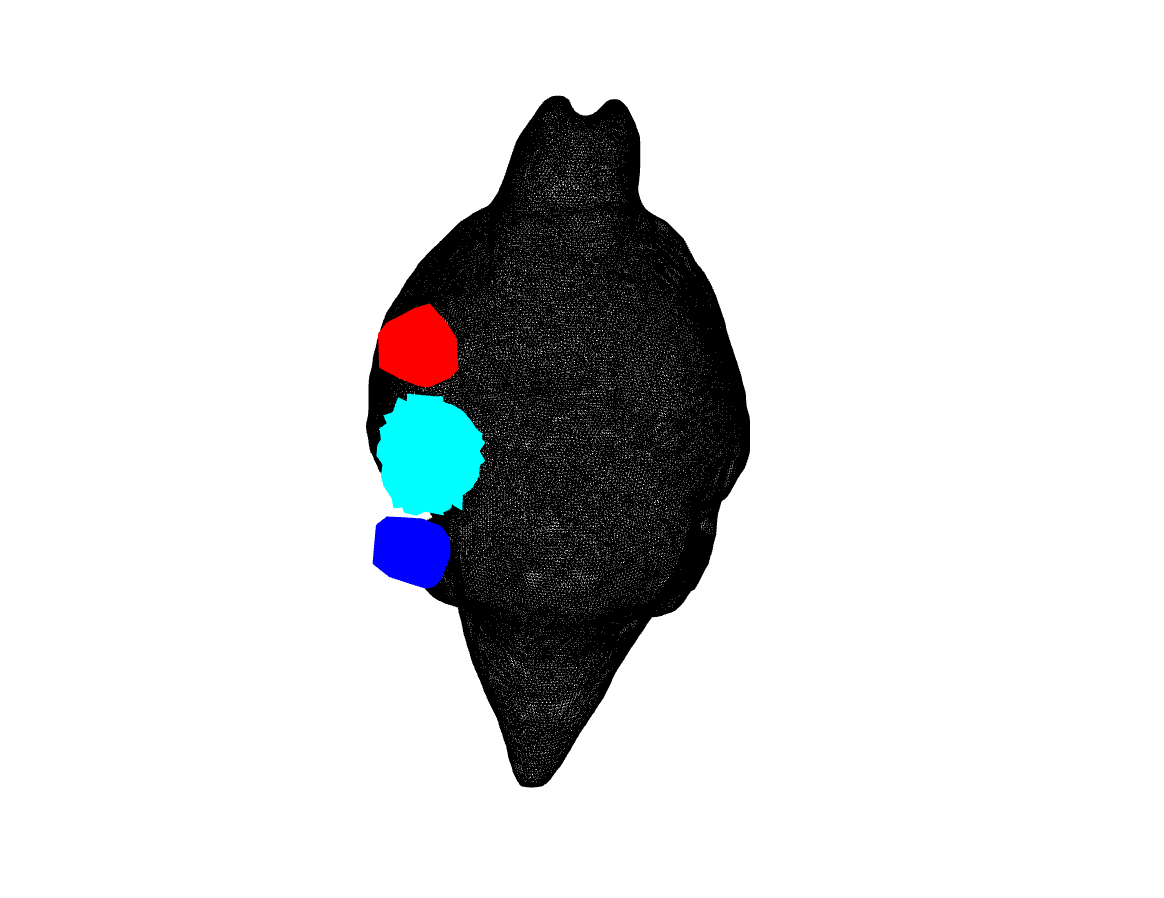

Stage MESH complete - 9.3478 seconds 


o.run(targetStage=Stage.MESH,show=true)

This mesh shows the electrodes in red (anode) and blue (cathode). For the craniotomy, the two tissue types that have been removed (skin and bone) are shown in cyan and magenta. 

### Stage EXPORT: export the mesh and model

Up until this stage, all changes were internal to the Matlab object (saved in *1x1_craniotomy.mat*), now we export files that the FEM solver GetDP can read. The *.msh* file contains information on the mesh (all the nodes, elements, labels and boundaries), and the *.pro* file tells GetDP which partial differential equations (PDE) model it needs to solve in this mesh.

o.run(targetStage=Stage.EXPORT)

Compute stage EXPORT
----Starting saveMesh...26-Jun-2025 13:10:14
----saveMesh elapsed time: 10.6679 seconds

----Starting savePro...26-Jun-2025 13:10:25
----savePro elapsed time: 0.0121 seconds

Stage EXPORT complete - 8.0149 seconds 


For troubleshooting, have a look at the *.pro* file in the project folder; it contains all the model specifications, including conductivity (in siemens per meter S/m) for the different tissues/elements.

type(file(o,"PRO"))

/* 
 .pro file created by EFMouse on 26-Jun-2025 13:10:25 
 ID: 1x1_craniotomy 
 Dir: /Users/rubensanchez/desktop/efmouse_sim/1x1_craniotomy 
 */

Group {

gray = Region[1];
csf = Region[2];
bone = Region[3];
skin = Region[4];
eye = Region[5];
Anode = Region[6];
Cathode = Region[7];
leftskin = Region[8];
leftbone = Region[9];
boundaryAnode = Region[10];
boundaryCathode = Region[11];
DomainC = Region[{gray,csf,bone,skin,eye,Anode,Cathode,leftskin,leftbone}];
AllDomain = Region[{gray,csf,bone,skin,eye,Anode,Cathode,leftskin,leftbone,boundaryAnode,boundaryCathode}];
}

Function {

sigma[gray] = 0.275;
sigma[csf] = 1.654;
sigma[bone] = 0.01;
sigma[skin] = 0.465;
sigma[eye] = 0.5;
sigma[Anode] = 0.3;
sigma[Cathode] = 0.3;
sigma[leftskin] = 2.5e-14;
sigma[leftbone] = 2.5e-14;
du_dnAnode[] = 69.185272;
du_dnCathode[] = -85.163364;
}

Jacobian {
  { Name Vol ;
    Case {
      { Region All ; Jacobian Vol ; }
    }
  }
  { Name Sur ;
    Case {
      { Region All ; Jacobian Sur ; }
    }
  }
}


This file can be opened in the GetDP gui to run it manually, but Stage.GETDP runs it for you.

### Stage GETDP: run GetDP

It will take GetDP between 15 and 30 minutes to compute the solutions of the Laplace equation (on 2024 Mac or Windows hardware). The results are saved in *_e.pos* and *_v.pos* files (in GetDP format). In the object the results are saved as .field and .voltage.

o.run(targetStage=Stage.GETDP,show=false);

Compute stage GETDP
Info    : Running '/Users/rubensanchez/Desktop/Klab/EFMouse/lib/getdp-3.5.0/bin/getdpMac /Users/rubensanchez/desktop/efmouse_sim/1x1_craniotomy/1x1_craniotomy.pro -solve EleSta_v -msh /Users/rubensanchez/desktop/efmouse_sim/1x1_craniotomy/1x1_craniotomy.msh -pos Map' [GetDP 3.5.0, 1 node, max. 1 thread]
Info    : Started (Thu Jun 26 13:10:54 2025, Wall = 0.00148392s, CPU = 0.014325s, Mem = 4.26953Mb)
Info    : Initializing Gmsh
Info    : Loading problem definition '/Users/rubensanchez/desktop/efmouse_sim/1x1_craniotomy/1x1_craniotomy.pro'
Info    : Selected Resolution 'EleSta_v'
Info    : Loading Geometric data '/Users/rubensanchez/desktop/efmouse_sim/1x1_craniotomy/1x1_craniotomy.msh'
Info    : System 'Sys_Ele' : Real
□P r e - P r o c e s s i n g . . .□
Info    : Treatment Formulation 'Electrostatics_v'
  0%    : Pre-processing                                          
 10%    : Pre-processing                                          
 20%    : Pre-processin

Use the `plotEf()` function to visualize the electric field in the X direction, and then the electric field magnitude.

----Starting plotEf...26-Jun-2025 13:19:05


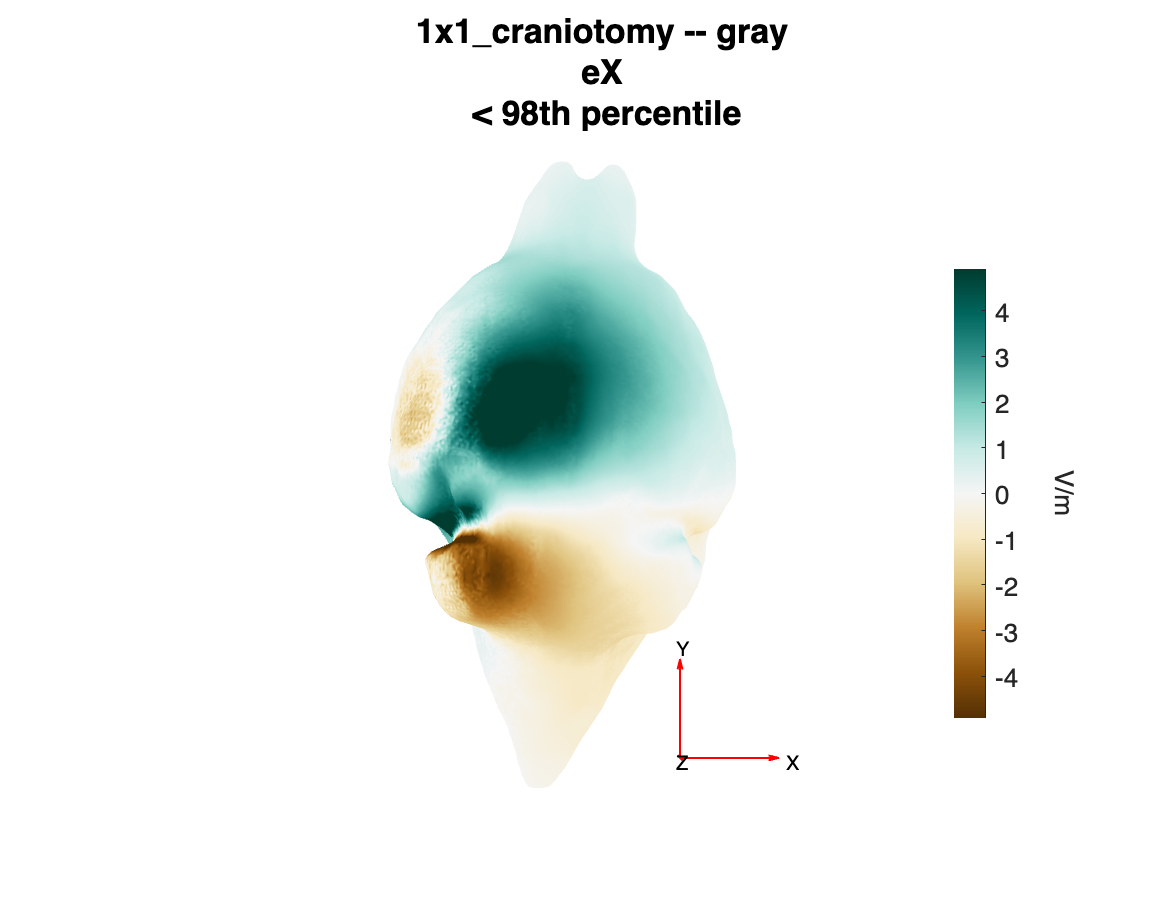

----plotEf elapsed time: 1.3682 seconds


plotEf(o,type='eX',percentile=98, tissue='gray');

----Starting plotEf...26-Jun-2025 13:19:06


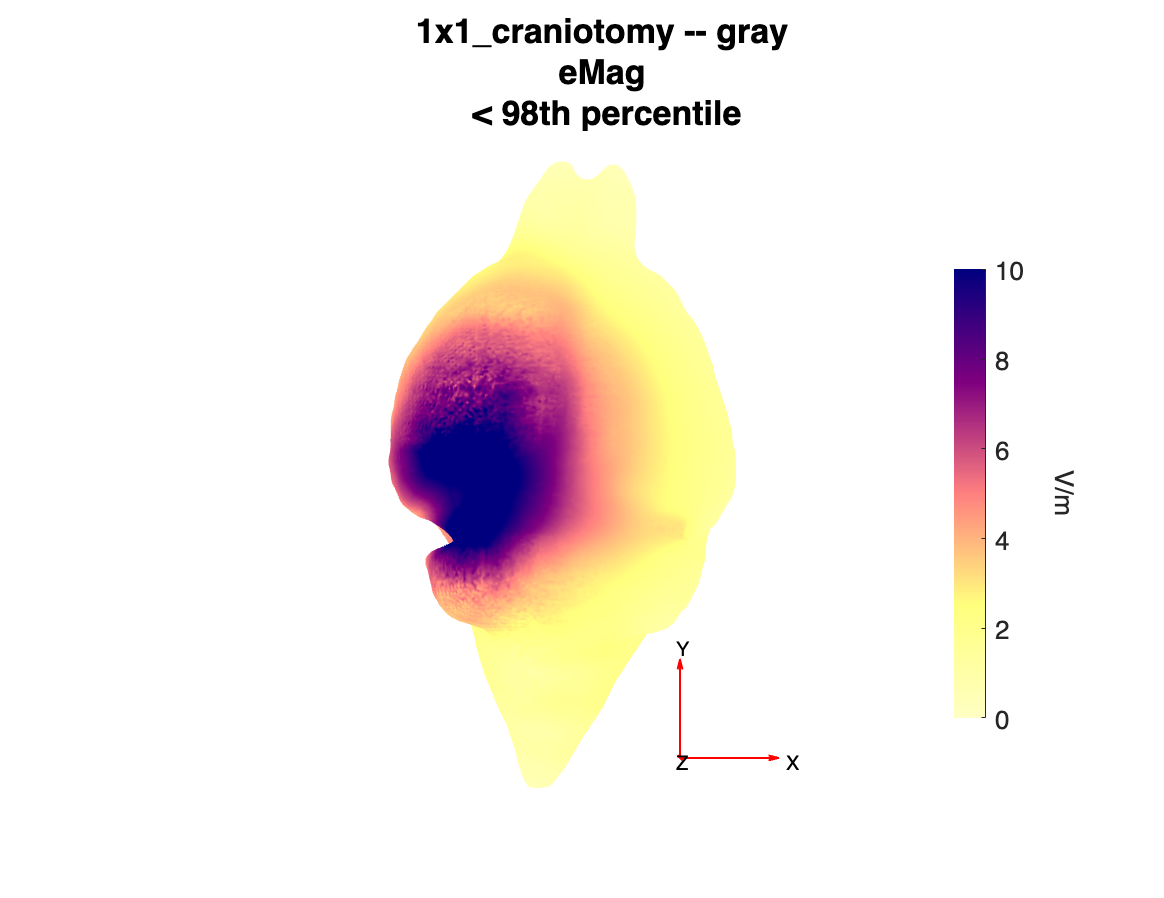

----plotEf elapsed time: 0.8799 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray');

We can also use `plotEf()` to visualize a brain slice perpendicular to a given axis. Here we show a frontal/coronal plane slice (perpendicular to the y axis) in the position of the anode electrode, a sagittal slice and a horizontal slice.

----Starting plotEf...26-Jun-2025 13:19:36


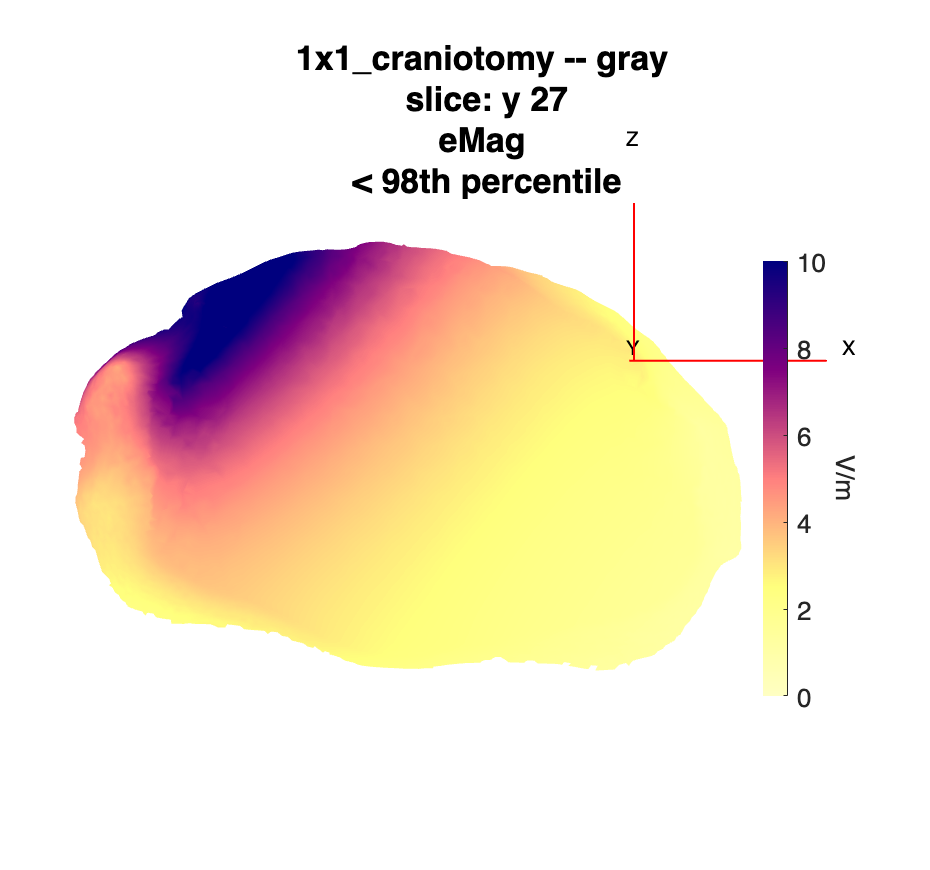

----plotEf elapsed time: 0.5767 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray',slice = true, slice_ax = "y",slice_pos = 27)

----Starting plotEf...26-Jun-2025 13:19:37


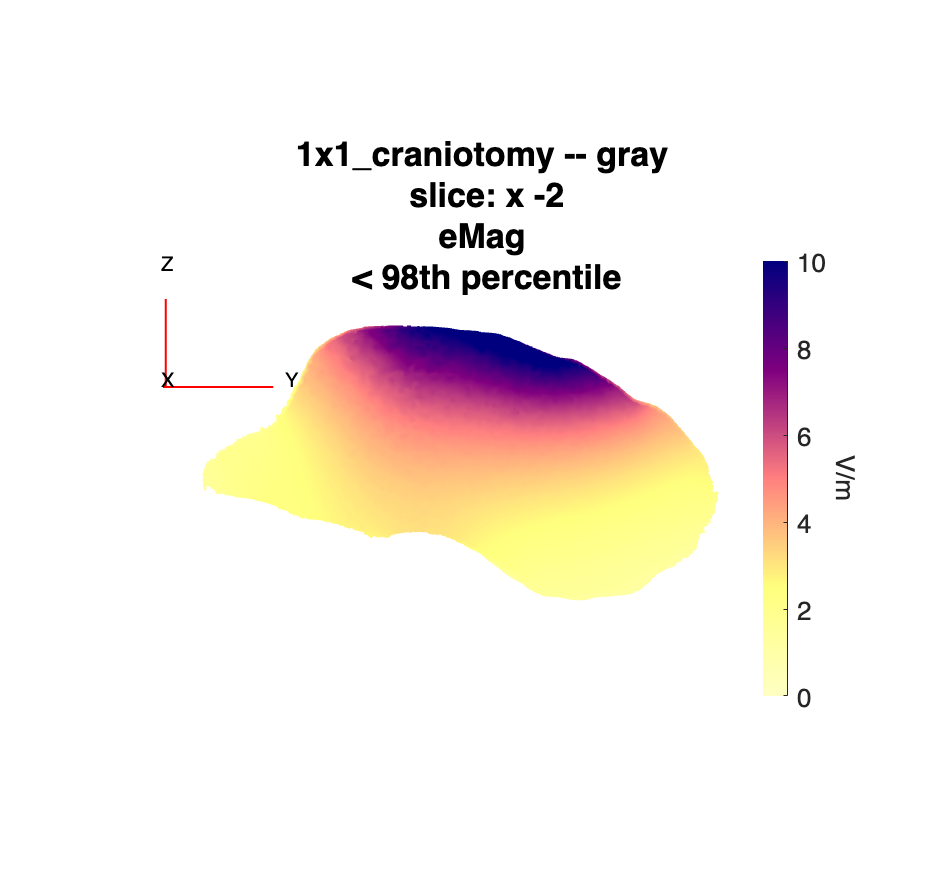

----plotEf elapsed time: 0.4956 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray',slice = true, slice_ax = "x",slice_pos = -2)

----Starting plotEf...26-Jun-2025 13:19:37


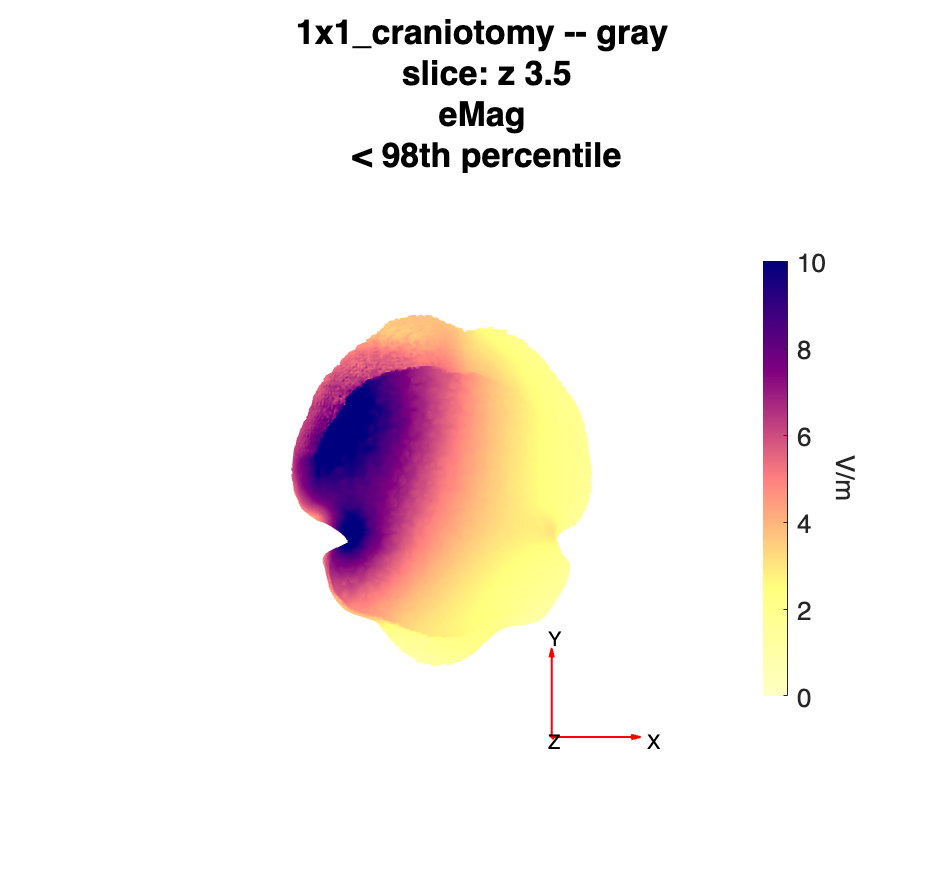

----plotEf elapsed time: 0.4441 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray',slice = true, slice_ax = "z",slice_pos = 3.5)

### **Tissue Based Analysis**

In general, we focus on the brain, but if necessary, we can compute electric field estimates for the rest of the mouse body for a full characterization of the anatomical effects of the electrical stimulation protocol. `leftbone `refers to the bone area removed during the craniotomy. The label is defined by joining the craniotomy tag (see Stage MESH above) and the tissue removed: `left `+ "bone": `leftbone.`

See Sanchez-Romero et al., (2025) for a full description of the electric field metrics.

summary = analyzeTissue(o,["skin" "gray" "leftbone"]);

----Starting analyzeTissue...26-Jun-2025 13:19:51
Electric field summary statistics for skin tissue
              mean        median        std         min         max  
            ________    ___________    ______    __________    ______

    eX       0.09732    -0.00017319    4.3424       -191.39    179.03
    eY      -0.44515    -2.1471e-05    3.9822       -319.35    141.49
    eZ       -0.1791     0.00062962    8.0599       -392.17    267.92
    eMag      1.4294       0.031948    9.8931    2.2395e-07    468.36

[Homogeneity ranges from 0 to 1]
Homogeneity = 0.3750, for ef_norm_mean: (-0.237 -0.078 0.280)

Electric field summary statistics for gray tissue
             mean       median      std    

### ROI Analysis

Now that we have the field estimates for each node in the mesh, we can do an ROI based analysis. For instance, a box ROI.

For the relative focality the reference area is the rest of the gray tissue.

See Sanchez-Romero et al.(2025), for definitions of relative focality and homogeneity. 

roi.shape = 'box';
roi.center = [-3.5,27.5 3.5];
roi.width = 2;  % Left/Right
roi.length = 2; % Anterior/Posterior
roi.thickness =1;  % Inferior/Superior
summary = analyzeRoi(o,roi,plot=true,foc_percentile_max=99.9,foc_threshold=40); % Define values for relative focality metric.

----Starting analyzeRoi...30-Jun-2025 12:01:54
Electric field summary statistics for a box roi in gray
             mean      median      std        min        max  
            _______    _______    ______    _______    _______

    eX       2.0809     2.0051     1.154    -1.1013     6.4772
    eY      -6.4497    -6.3908    1.4705    -11.319    -2.6265
    eZ      -1.7913    -1.5099    1.6226    -6.6211     2.6618
    eMag     7.2875     7.1736    1.4679     4.1799      11.73

[Relative focality ranges from 0 to 1]
Relative focality = 0.8444, with 160508 reference nodes (cutoff: eMag > 40.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9628, for ef_norm_mean: (0.297 -0.882 -0.246)


% Rotate and zoom to view the (yellow) box ROI underneath the craniotomy
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

For comparison, define an analogous box ROI but in the right hemisphere

roiRight = roi;
roiRight.center(1)  =-1* roi.center(1)

roiRight = struct with fields:
        shape: 'box'
       center: [3.5000 27.5000 3.5000]
        width: 2
       length: 2
    thickness: 1


summary = analyzeRoi(o,roiRight,plot=true,foc_percentile_max=99.9,foc_threshold=40);

----Starting analyzeRoi...30-Jun-2025 12:01:56
Electric field summary statistics for a box roi in gray
              mean       median       std        min         max  
            ________    ________    _______    ________    _______

    eX       0.36948     0.40542     0.3881    -0.89685     1.2826
    eY       -2.0265     -1.9922    0.33608     -3.0624    -1.2929
    eZ      -0.20111    -0.22507    0.13439    -0.50969    0.24162
    eMag      2.1104      2.0896    0.33342      1.3748     3.0788

[Relative focality ranges from 0 to 1]
Relative focality = 0.0805, with 160925 reference nodes (cutoff: eMag > 40.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9804, for ef_norm_mean: (0.173 -0.960 -0.10

% Rotate and zoom to view the (yellow) box ROI in the right hemisphere
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

### Stage ATLAS: Volumetric/Atlas Analysis

The mesh coordinates are not particularly intuitive, and you may want to estimate electric fields in specific brain areas (as defined in an atlas). EFMouse does this in reference to the Allen Mouse Brain Atlas. 

To use this, we first have to map the mesh-based results to the Allen Atlas. This is Stage ATLAS of the pipeline. This stage first exports the mesh-based results to a volume (using linear interpolation) and then uses the FLIRT tool in FSL to transform this volume to the coordinates of the Allen Atlas. Note that the alignment between the Digimouse mesh and the Allen Atlas is not perfect because they are based on different imaging modalities (and different mouse strains). (See Sanchez-Romero et al., (2025), for more details.) 

This will fail if FSL is not installed.

o.run(targetStage=Stage.ATLAS,startStage=Stage.ATLAS)

Compute stage ATLAS
----Starting computeVoxelSpace...26-Jun-2025 13:21:07
----Exporting to NIFTI volumes 
---/Users/rubensanchez/desktop/efmouse_sim/1x1_craniotomy/1x1_craniotomy_efm.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/1x1_craniotomy/1x1_craniotomy_efX.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/1x1_craniotomy/1x1_craniotomy_efY.nii.gz created
---/Users/rubensanchez/desktop/efmouse_sim/1x1_craniotomy/1x1_craniotomy_efZ.nii.gz created
----computeVoxelSpace elapsed time: 8.2106 seconds
Stage ATLAS complete - 16.3096 seconds 


### Atlas Based Analysis

Once stage 5 has completed we can query electric fields based on a region that is defined in the Allen Atlas. For instance: 'Visual areas' for the left hemisphere.

For the relative focality the reference area is the rest of the Allen atlas "Isocortex".

T = analyzeAtlas(o,"Visual areas",hemisphere="left",foc_threshold=40,foc_percentile_max=99.9,foc_reference='Isocortex');

----Starting analyzeAtlas...30-Jun-2025 12:04:03
Area: Visual areas (1.0% of brain) , hemisphere left 
              mean       median      std         min        max  
            ________    ________    ______    _________    ______

    eX        2.0337      2.3565    1.6565      -6.6171    5.7395
    eY       -8.4987     -9.1783     2.501        -12.9         0
    eZ      -0.77243    -0.79121      2.08      -6.2738    7.2417
    eMag      9.1387      9.8214    2.6162    0.0042919    14.188

[Relative focality ranges from 0 to 1]
Relative focality = 0.8062, with 92410 reference voxels (cutoff: eMag > 40.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9626, for ef_norm_mean: (0.233 -0.930 -0.085)
---

For comparison, we can query results for the right hemisphere, which is contra-lateral from the targeted area.

T = analyzeAtlas(o,"Visual areas",hemisphere="right",foc_threshold=40,foc_percentile_max=99.9,foc_reference='Isocortex');

----Starting analyzeAtlas...30-Jun-2025 12:04:03
Area: Visual areas (1.0% of brain) , hemisphere right 
              mean       median        std         min        max  
            ________    _________    _______    _________    ______

    eX         0.375      0.20884     0.5154     -0.90697    2.4466
    eY       -2.5165       -2.735     1.0907      -4.4835         0
    eZ      0.036943    -0.040733    0.37537     -0.88274    1.1698
    eMag      2.6047       2.8034     1.1365    0.0028405    4.4899

[Relative focality ranges from 0 to 1]
Relative focality = 0.2023, with 92457 reference voxels (cutoff: eMag > 40.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9774, for ef_norm_mean: (0.137 -0.96

## Tips and Tricks

- The run function can be called with any `targetStage` from Stage.INIT to Stage.ATLAS. Stages that have already been completed will not be run again, and all stages that need to be completed to reach the `targetStage` will be completed in turn.

- IMPORTANT: To continue working with a model from a previous Matlab session, you create an `EFMouse` object with the `dir` and `ID` input arguments to specify the folder with the (previously saved) results and the ID of the montage. For instance, to open the simulation from the tutorial at the stage where it was last saved:

o = EFMouse(dir='/Users/rubensanchez/desktop/efmouse_sim/1x1_craniotomy',ID='1x1_craniotomy')

o = EF Mouse Model (label: 1x1_craniotomy) in directory /Users/rubensanchez/desktop/efmouse_sim/1x1_craniotomy (stage=ATLAS).